TCET-751 – Simulation Assignment #1

Pulse bandwidth calculations

Rahul Gulia

September 6, 2021

Calculate the power bandwidth of a rectangular pulse wave.

clc;
clear all;
close all;

clearvars
%% Generate signal
T = 1;          % pulse duration
ts = 0.05;      % sampling interval
fN = 1/(2*ts);  % Nyquist frequency
[p, t] = rectangularpulse(T, ts);

%% Analysis
% calculate spectrum
[m, f] = getspectrum(p, ts, 10);

% calculate total power (B100)
P = 1/(length(m))*sum(m.*m);
fprintf("Pulse power (t) is: %.4f\n", P);

Pulse power (t) is: 1.0000


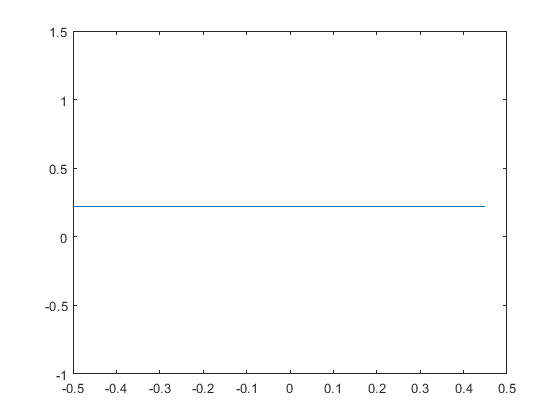

plot(t,p)

% Estimate power in a given band
x = 0.098;
fX = x*fN;
mm = m(f>-fX & f<fX);
PXX = (1/length(m))*sum(mm.*mm);

fprintf("Bandwidth of rectangular pulse: %.4f\n", fX)

Bandwidth of rectangular pulse: 0.9800


fprintf("Power in specified band: %.4f\n", PXX);

Power in specified band: 0.9037


fprintf("Power ratio: %.4f\n", PXX/P);

Power ratio: 0.9037


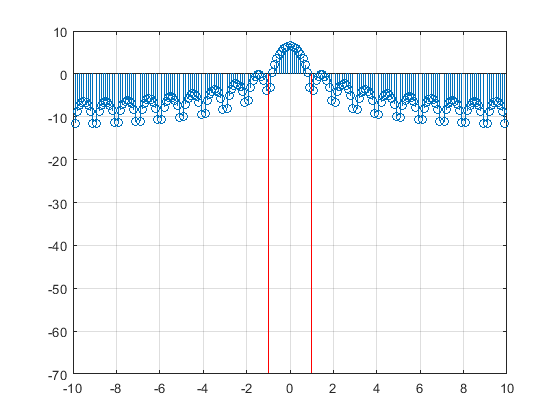


% plot
stem(f,10*log10(m))
hold on
plot([fX fX], 10*log10([.0000001 1]), 'r');
plot([-fX -fX], 10*log10([.0000001 1]), 'r');
hold off
grid on